clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='naca1412';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=18;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus


## load foildatabase

fileName='foils_imported.dat';

foil_db=readtable(fileName)

foil_db = 12×7 table
      foil_name       AoA_eps    CL_eps    CD_eps     AoA_lift    CL_lift    CD_lift
    ______________    _______    ______    _______    ________    _______    _______

    {'fx84w097'  }       7       1.0105    0.01803       11       1.1829     0.05986
    {'fx84w127'  }       9       1.2775    0.02398       14       1.3242     0.06805
    {'n63212'    }       6       0.7485    0.01722        9       0.9323     0.04305
    {'naca1408'  }       4        0.579    0.01308        8       0.8962     0.04622
    {'naca1410'  }       5       0.6834    0.01528       10       1.0252     0.05438
    {'naca1412'  }       6       0.7861    0.01776       11       1.1294     0.04802
    {'naca23012' }       5       0.7214    0.02052       12 

## check if foil exists in db

Index =find(strcmp(name,foil_db.foil_name))

Index = 6

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof=blade_root(R)
       if r>= 0.15*R
            prof(3)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
       else
            disp('Profil ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')    
       end       
     else
       if check_existing(prof,r) == 0 & r>= 0.15*R
            l=length(prof);
            prof(l+1)=foil_transform(R,r,name,lamda_A,z, t,foil_db);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits oder ist zu nah an der Blattwurzel. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


Index = 6

profile =     1.0000    0.9503    0.9004    0.8006    0.7006    0.6005    0.5003    0.4000    0.2993    0.2489    0.1986    0.1483    0.0982    0.0733    0.0485    0.0238    0.0116         0    0.0134    0.0262    0.0515    0.0767    0.1018    0.1517    0.2014    0.2511    0.3008    0.4000    0.4997    0.5995    0.6994    0.7994    0.8996    0.9497    1.0000
    0.0013    0.0097    0.0175    0.0318    0.0441    0.0545    0.0627    0.0680    0.0694    0.0680    0.0649    0.0595    0.0512    0.0454    0.0379    0.0273    0.0195         0   -0.0183   -0.0249   -0.0332   -0.0386   -0.0424   -0.0473   -0.0499   -0.0508   -0.0506   -0.0480   -0.0432   -0.0367   -0.0291   -0.0207   -0.0114   -0.0065   -0.0013


## plot der profile

bld_plot(prof)

l = 11

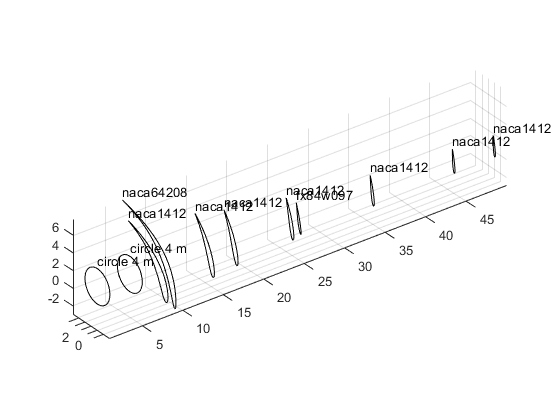

grid on